# Lecture: MATLAB Review 3 Code

## Formatting values using fprintf

clear, clc
fprintf('The value of pi is %7.5f.\n',pi)

The value of pi is 3.14159.


## while loop - projectile example

The Cartesian coordinates of a projectile launched with an initial velocity ($v_0$) and angle ($\theta_0$) can be computed with: 

$x=v_0 \;\cos \left(\theta_0 \right)t$, $y=v_0 \;\sin \left(\theta_0 \right)t-0\ldotp 5{\textrm{gt}}^2$

***At what time (to the nearest 100th of a second) will the projectile hit the ground if ***$v_0 =5\;$***m/s and ***$v_0 =50\degree$***?***

v0 = 5; % initial velocity [m/s]
theta0 = 50; % initial angle [in degrees]
g = 9.81; % accel. due to gravity [m/s/s]

Generate an anonymous function

% equation for projectile height 

Define the first t value that won't give us a zero for height

% current time [in seconds]
% current height [in m]

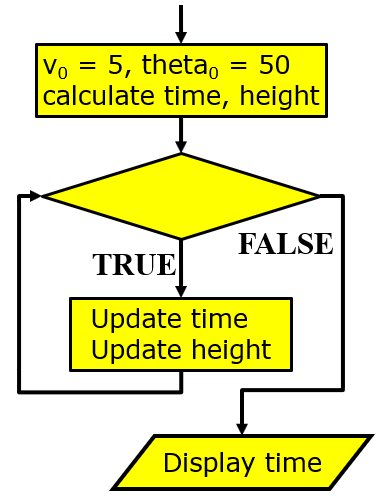

v0 = 5;
theta0 = 50;
g = 9.81;

y = @(t) v0*sind(theta0)*t-0.5*g*t^2; % height in meters

t = 0.01; %initial time

height = y(t);

while height > 0
    t = t + 0.01;
    height = y(t);
end    

fprintf('The ball will hit the ground at %.2f seconds', t)

The ball will hit the ground at 0.79 seconds

## while-break loop - divide and average example

clear, clc

The square root for any positive #, $a$, can be approximated by: $x=\frac{x+\frac{a}{x}}{2}$  

The error can be calculated using: $\varepsilon =\left|\frac{x_{\textrm{new}} -x_{\textrm{old}} }{x_{\textrm{new}} }\right|$ 

***Evaluate ***$a=5$*** for ***$\varepsilon ={10}^{-3}$

a = 5;
errTol = 10^-3;
x = a/2; % start out by dividing

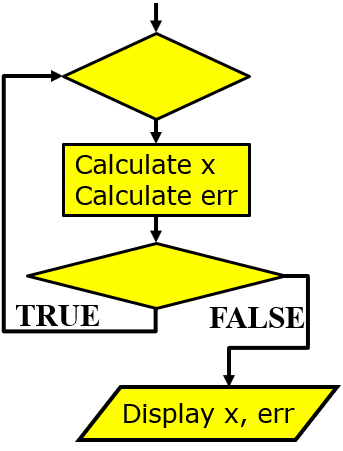

while true
    xold = x;
    x= (xold +a/xold)/2;
    err = abs((x-xold)/2);
    if err < errTol
        break
    end
end

fprintf('The approximate root of %d is %.3f with an error of %.5f.\n',a,x,err)

The approximate root of 5 is 2.236 with an error of 0.00002.


## for loop example - Calculating variation

clear, clc

***Which patient shows greater variation?***

## Table example 

clear, clc

### bad table

Make vectors of the first 5 integers and their squares.

**Output the results in a table like the one shown.**

`number square`

`------ ------`

number = 1:5;
square = number.^2;
fprintf('number square\n')

number square


fprintf('------ ------\n')

------ ------


for k = number
    fprintf('&6d %6d\n',number(k),square(k))
end

&6d      1
&6d      1
&6d      2
&6d      4
&6d      3
&6d      9
&6d      4
&6d     16
&6d      5
&6d     25


### good table

number = 1:5;
square = number.^2;

for k = number
    if k == 1
    fprintf('number square\n')
    fprintf('------ ------\n')
    end
    fprintf('%6d %6d\n',number(k),square(k))
end

number square


------ ------


     1      1
     2      4
     3      9
     4     16
     5     25


## Helper Functions

% VARIATION - calculate the sum of squares of the provided vector
% Parameter:
%   data - vector containing data for which we are calculating variation
% Returns:
%   v - variation based on sum of squares of diff. from the mean


$v=\sum_{k=1}^n {\left(x_k -\bar{x} \right)}^2$